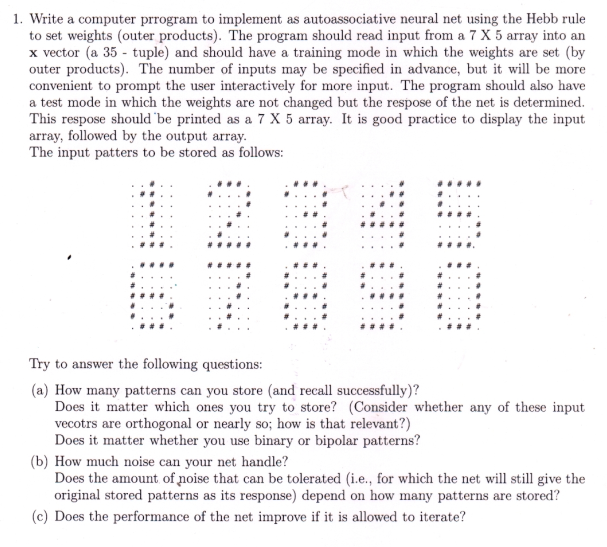

one = [-1 -1 1 -1 -1;
       -1  1 1 -1 -1;
       -1 -1 1 -1 -1;
       -1 -1 1 -1 -1;
       -1 -1 1 -1 -1;
       -1 -1 1 -1 -1;
       -1  1 1  1 -1;
        ];
two = [-1  1  1  1 -1;
        1 -1 -1 -1  1;
       -1 -1 -1 -1  1;
       -1 -1 -1  1 -1;
       -1 -1  1 -1 -1;
       -1  1 -1 -1 -1;
        1  1  1  1  1;
        ];
three = [-1	1	1	1	-1;
          1	-1	-1	-1	1;
         -1	-1	-1	-1	1;
         -1	-1	1	1	-1;
         -1	-1	-1	-1	1;
          1	-1	-1	-1	1;
         -1	1	1	1	-1;];
four =[-1 -1 -1 -1  1;
       -1 -1 -1  1  1;
       -1 -1  1 -1  1;
       -1  1 -1 -1  1;
        1  1  1  1  1;
       -1 -1 -1 -1  1;
       -1 -1 -1 -1  1;
        ];

five =[ 1  1  1  1  1;
        1 -1 -1 -1 -1;
        1 -1 -1 -1 -1;
        1  1  1  1 -1;
       -1 -1 -1 -1  1;
       -1 -1 -1 -1  1;
        1  1  1  1 -1;
        ];

six =[ -1  1  1  1  1;
        1 -1 -1 -1 -1;
        1 -1 -1 -1 -1;
        1  1  1  1 -1;
        1 -1 -1 -1  1;
        1 -1 -1 -1  1;
       -1  1  1  1 -1;
        ];

seven=[ 1  1  1  1  1;
       -1 -1 -1 -1  1;
       -1 -1 -1  1 -1;
       -1 -1 -1  1 -1;
       -1 -1  1 -1 -1;
       -1 -1  1 -1 -1;
       -1  1 -1 -1 -1;
        ];

eight=[-1  1  1  1 -1;
        1 -1 -1 -1  1;
        1 -1 -1 -1  1;
       -1  1  1  1 -1;
        1 -1 -1 -1  1;
        1 -1 -1 -1  1;
       -1  1  1  1 -1;
        ];

nine= [-1  1  1  1 -1;
        1 -1 -1 -1  1;
        1 -1 -1 -1  1;
       -1  1  1  1  1;
       -1 -1 -1 -1  1;
       -1 -1 -1 -1  1;
        1  1  1  1 -1;
        ];

zero =[-1  1  1  1 -1;
        1 -1 -1 -1  1;
        1 -1 -1 -1  1;
        1 -1 -1 -1  1;
        1 -1 -1 -1  1;
        1 -1 -1 -1  1;
       -1  1  1  1 -1;
        ];

input = containers.Map({1,2,3,4,5,6,7,8,9,0},{one,two,three,four,five,six,seven,eight,nine,zero});

% Number of patterns to store
% 0,1,2,...,pstore
pstore = 9

pstore = 9

% Allow to iterate
allow_iterate = false;
max_iter = 5;

w = zeros(35,35);
for i = 0:pstore
    a = reshape(input(i),[],1) ;
    w = w + a*a';
end
w

w =     10    -4     0     4    -2    -2     4    -2     4     6     0     4     4    -4    -4     4     2    -2     2     6    -6    -2     4     8     0     4     6    -6     6    -4    -6     0    -4    -4     2
    -4    10     6     2     0     4     2     8    -6    -4     2    -6    -2     6     6    -6    -8     4    -8    -8     8     8    -6    -6     6    -6    -4     8    -4     2     4    -2     6     6    -4
     0     6    10     6     4     4     2     4    -2     0     6    -2    -2     2     2    -2    -4     4    -8    -4     4     4    -2    -2     2    -2     0     4     0    -2     0     2     6     6    -4
     4     2     6    10     4     4     2     0     2     4     2     2     2    -2    -2     2     0     0    -4     0     0     0     2     2    -2     2     4     0     4    -6    -4     2     2     2     0
    -2     0     4     4    10     6    -4    -2     0     2     4     4     0    -4    -4     0     2    -2    -2    -2    -2    -2     4     0    -4  

% Recalling the patterns
output = containers.Map("KeyType","int32","ValueType","any");
for i = 0:pstore
    a =  reshape(input(i),[],1);
    out = a'*w ;
    out = func(out,a) ;
    if allow_iterate
        for k = 1:max_iter
            out = out*w;
            out = func(out,a);
        end
    end
    output(i) = reshape(out,7,5);
end

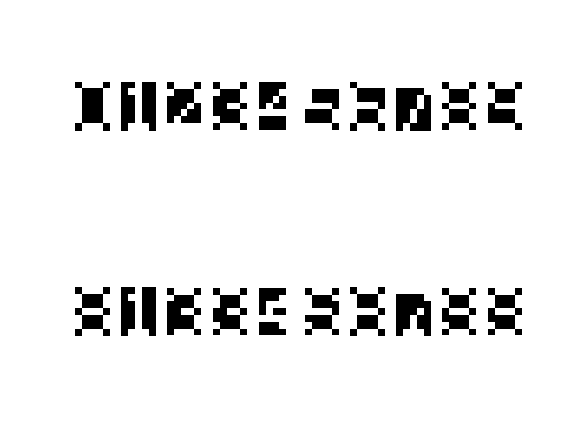

for i = 0:pstore
    subplot(2,pstore+1,i+1),imshow(input(i));
    subplot(2,pstore+1,pstore+2+i),imshow(output(i));
end

input_bi = containers.Map({1,2,3,4,5,6,7,8,9,0},{one,two,three,four,five,six,seven,eight,nine,zero});
for i = 0:pstore
    a = input_bi(i);
    a(a==-1)=0 ;
    input_bi(i)=a;
end


input_bi(0)

ans =      0     1     1     1     0
     1     0     0     0     1
     1     0     0     0     1
     1     0     0     0     1
     1     0     0     0     1
     1     0     0     0     1
     0     1     1     1     0


W = zeros(35,35);
for i = 0:pstore
    a = reshape(input_bi(i),[],1) ;
    W = W + (2*a-1)*(2*a-1)';
end
W

W =     10    -4     0     4    -2    -2     4    -2     4     6     0     4     4    -4    -4     4     2    -2     2     6    -6    -2     4     8     0     4     6    -6     6    -4    -6     0    -4    -4     2
    -4    10     6     2     0     4     2     8    -6    -4     2    -6    -2     6     6    -6    -8     4    -8    -8     8     8    -6    -6     6    -6    -4     8    -4     2     4    -2     6     6    -4
     0     6    10     6     4     4     2     4    -2     0     6    -2    -2     2     2    -2    -4     4    -8    -4     4     4    -2    -2     2    -2     0     4     0    -2     0     2     6     6    -4
     4     2     6    10     4     4     2     0     2     4     2     2     2    -2    -2     2     0     0    -4     0     0     0     2     2    -2     2     4     0     4    -6    -4     2     2     2     0
    -2     0     4     4    10     6    -4    -2     0     2     4     4     0    -4    -4     0     2    -2    -2    -2    -2    -2     4     0    -4  


% Recalling the patterns
output_bi = containers.Map("KeyType","int32","ValueType","any");
for i = 0:pstore
    a =  reshape(input_bi(i),[],1);
    out = a'*W ;
    for j = 1:size(out,2)
        if out(j) > 0
            out(j) = 1 ;
        elseif out(j) < 0
            out(j) = 0 ;
        else
            out(j) = a(j);
        end
    end
    output_bi(i) = reshape(out,7,5);
end

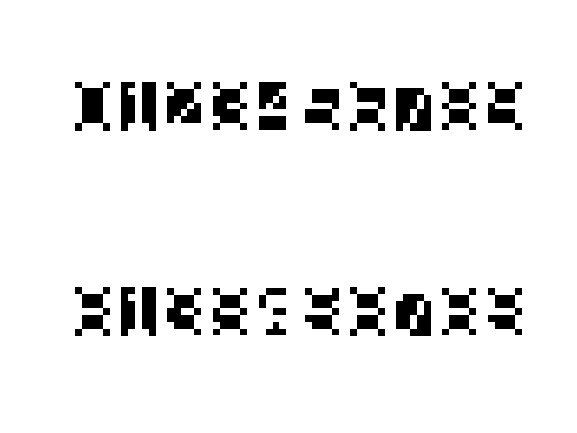

for i = 0:pstore
    subplot(2,pstore+1,i+1),imshow(input_bi(i));
    subplot(2,pstore+1,pstore+2+i),imshow(output_bi(i));
end

% We can store maximum of 3 patterns and recall successfully
% Binary or bipolar doesn't matter much

% Checking the patterns are orthogonal
for i = 0:9
    for j = i+1:9
        if dot(reshape(input(i),[],1),reshape(input(j),[],1)) == 0
            fprintf("patterns %d and %d are othogonal\n",i,j);
        else
            fprintf("patterns %d and %d are not othogonal\n",i,j);
        end
    end
end

patterns 0 and 1 are not othogonal
patterns 0 and 2 are not othogonal
patterns 0 and 3 are not othogonal
patterns 0 and 4 are not othogonal
patterns 0 and 5 are not othogonal
patterns 0 and 6 are not othogonal
patterns 0 and 7 are not othogonal
patterns 0 and 8 are not othogonal
patterns 0 and 9 are not othogonal
patterns 1 and 2 are not othogonal
patterns 1 and 3 are not othogonal
patterns 1 and 4 are not othogonal
patterns 1 and 5 are not othogonal
patterns 1 and 6 are not othogonal
patterns 1 and 7 are not othogonal
patterns 1 and 8 are not othogonal
patterns 1 and 9 are not othogonal
patterns 2 and 3 are not othogonal
patterns 2 and 4 are not othogonal
patterns 2 and 5 are not othogonal
patterns 2 and 6 are not othogonal
patterns 2 and 7 are not othogonal
patterns 2 and 8 are not othogonal
patterns 2 and 9 are not othogonal
patterns 3 and 4 are not othogonal
patterns 3 and 5 are not othogonal
patterns 3 and 6 are not othogonal
patterns 3 and 7 are not othogonal
patterns 3 and 8 are

% None of the patterns are orthogonal

% Checking with noised patterns
percent = 20

percent = 20

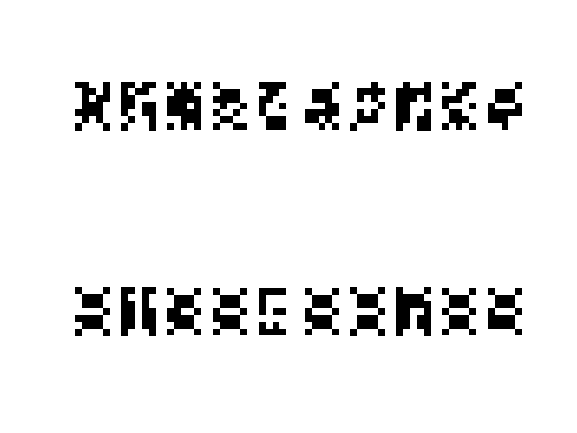

inputn = containers.Map({1,2,3,4,5,6,7,8,9,0},{noise(one,percent),noise(two,percent),noise(three,percent),noise(four,percent),noise(five,percent),noise(six,percent),noise(seven,percent),noise(eight,percent),noise(nine,percent),noise(zero,percent)});

% Recalling the patterns
outputn = containers.Map("KeyType","int32","ValueType","any");
for i = 0:pstore
    a =  reshape(inputn(i),[],1);
    out = a'*w ;
    for j = 1:size(out,2)
        if out(j) > 0
            out(j) = 1 ;
        elseif out(j) < 0
            out(j) = -1 ;
        else
            out(j) = a(j);
        end
    end
    outputn(i) = reshape(out,7,5);
end
for i = 0:pstore
    subplot(2,pstore+1,i+1),imshow(inputn(i));
    subplot(2,pstore+1,pstore+2+i),imshow(outputn(i));
end

% 20% noised patterns can be recalled successfully... if three patterns are
% stored

% Performance is not improved if iterations are allowd

function out = func(out,a)
    for j = 1:size(out,2)
        if out(j) > 0
            out(j) = 1 ;
        elseif out(j) < 0
            out(j) = 0 ;
        else
            out(j) = a(j);
        end
    end
end


function A = noise(X,per)
    k = numel(X);
    n = ceil((k*per)/100) ;
    index = randi(k,n,1);
    for i = index
        X(i) = X(i)*-1 ;
    end
    A=X;
end